# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file="D:\Documents\Termoeconomia\TaesLab\Examples\gturbo\gturbo_model.json";
model=ThermoeconomicTool(file,'Debug',false);

### Define Waste Analysis Parameters

WasteFlows=convertCharsToStrings(model.WasteFlows);
model.ActiveWaste=convertStringsToChars(WasteFlows(1));

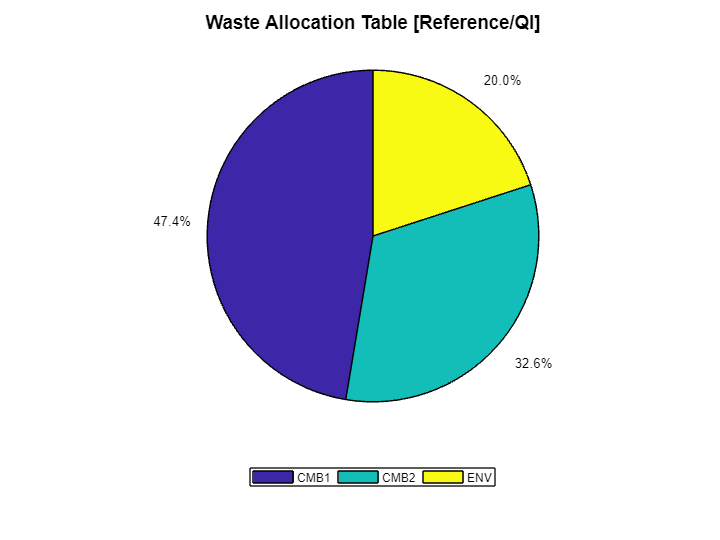

model.setWasteType(WasteFlow,'RESOURCES');
model.setWasteRecycled(WasteFlow,0.2);
showGraph(model,cType.Tables.WASTE_ALLOCATION,WasteFlow);

### Compute Exergy Cost and show results

printResults(model.wasteAnalysis)

Waste Definition Table

Key  Type              Recycling (%)
—————————————————————————————————————
QI   RESOURCES              20.00
QG   IRREVERSIBILITY        90.00


Waste Allocation Table  (%)

 Key          QI        QG
———————————————————————————
 CMB1      47.37      3.62
 CMB2      32.63      3.63
 CMP1       0.00      0.46
 CMP2       0.00      0.61
 TRB1       0.00      0.30
 TRB2       0.00      0.27
 PHTR       0.00      1.12
 ENV       20.00     90.00


Direct Cost Recycling Analysis (J/J)

 Recycle (%)         WN        QI
——————————————————————————————————
      0          1.9227    2.2024
     10          1.9114    2.1895
     20          1.9003    2.1768
     30          1.8894    2.1643
     40          1.8785    2.1518
     50          1.8678    2.1396
     60          1.8572    2.1274
     70          1.8467    2.1154
     80          1.8364    2.1035
     90          1.8261    2.0918
    100          1.8160    2.0802



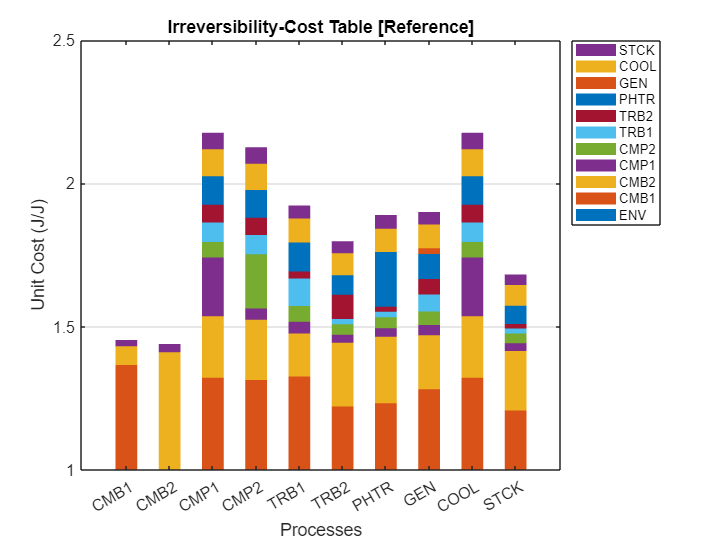

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

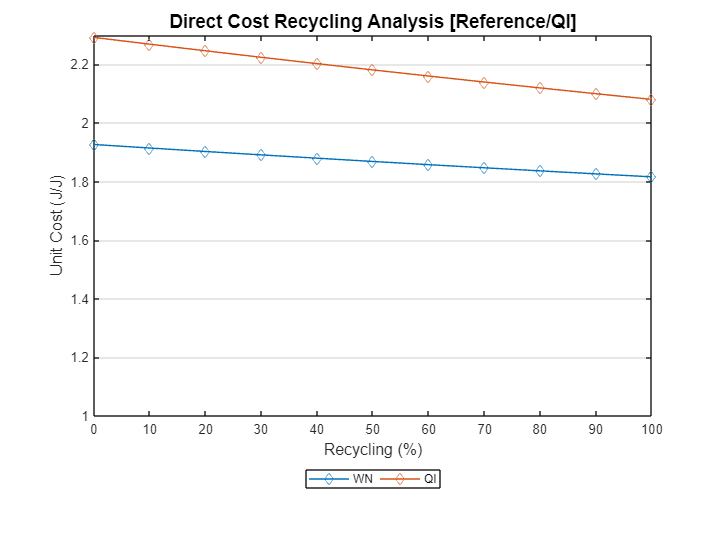

model.Recycling=true;
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);